Compute the inductance of a planar spiral inductor.

Based on the following white paper: [Simple Accurate Expressions for Planar Spiral Inductances](http://smirc.stanford.edu/papers/JSSC99OCT-mohan.pdf)

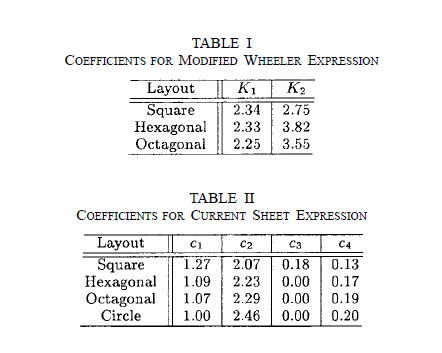

#### Modifed Wheeler Method

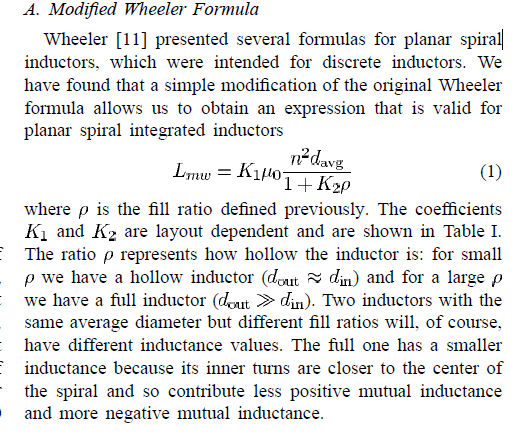

#### Current Sheet Method

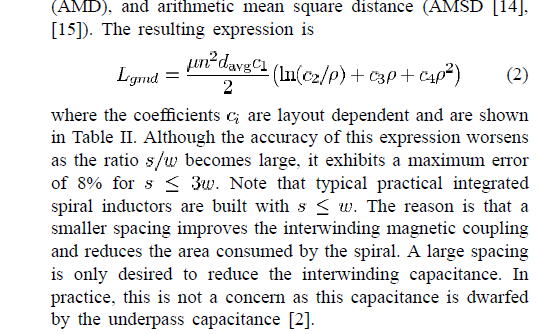

#### Data Fitted Monomial Method 

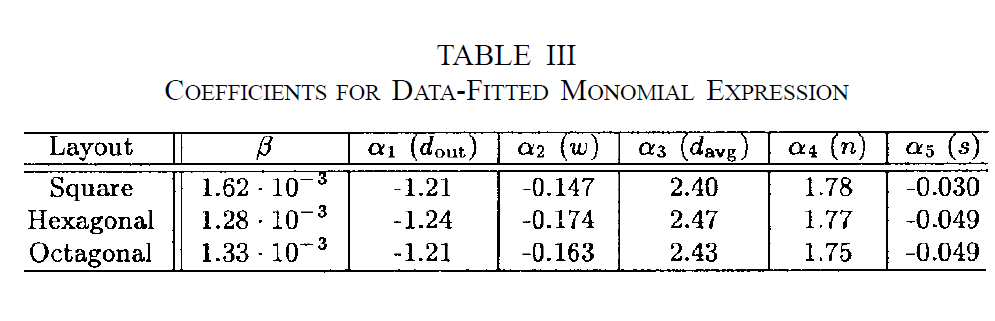

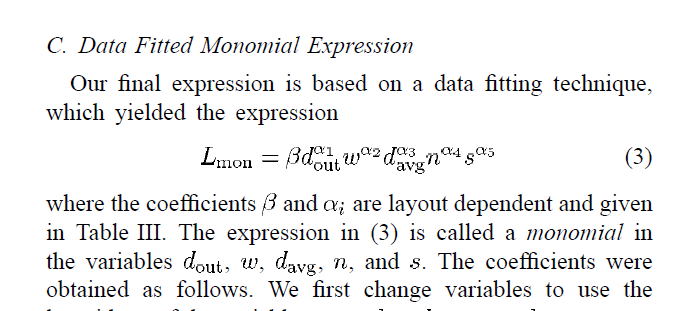

- dout: Outer diameter [m]

- din: Inner diameter [m]

- n: Number of turns

- w: Conductor width [m]

- s: Conductor spacing [m]

- geometry: Planar spiral geometry: "square", "hexagonal","octagonal" or "circular"

- mu_r: Relative permeability, defaults to 1.0 (air) if not specified

function [Lmw, Lcs, Lmf] = computePlanarSpiralInductance(dout, din, n, w, s, geometry, mu_r)

d_out = dout;   % m
d_in = din; % m
w_in = w;   % m
s_in = s;   % m

if d_in > d_out
    error("computePlanarSpiralInductance: din > dout");
end

% If relative Permeability not specified, default to that of air
if nargin == 6
   mu_r = 1.0;   % Relative Permeability of air
end

mu0 = 4*pi*1e-7; % Permeability of free space in H/m
mu = mu_r*mu0;    % Permeability of air is approximately mu0

Lmw = -1;
Lcs = -1; 
Lmf = -1;


davg = 0.5*(d_out+d_in);          % average diameter
rho = (d_out-d_in)/(d_out+d_in);    % fill ratio

switch geometry
    case "square"
        % Modified wheeler coeff
        K1 = 2.34;
        K2 = 2.75;
        Lmw = K1*mu*(((n^2)*davg)/(1+K2*rho));
        % Current sheet coefficients
        c1 = 1.27;
        c2 = 2.07;
        c3 = 0.18;
        c4 = 0.13;
        Lcs = ((mu*(n^2)*davg*c1)/2)*( log(c2/rho) + c3*rho + c4*rho^2 );
        if s_in <= 3*w_in
            warning("computePlanarSpiralInductance: s <= 3w, Lcs computation will exhibit maximum error of 8 %");
        end
        % Monomial exp coeff
        beta = 1.62e-3;
        alpha1 = -1.21;
        alpha2 = -0.147;
        alpha3 = 2.40;
        alpha4 = 1.78;
        alpha5 = -0.030;
        Lmf = beta*(d_out^alpha1)*(w_in^alpha2)*(davg^alpha3)*(n^alpha4)*(s_in^alpha5);
    case "hexagonal"
        % Modified wheeler coeff
        K1 = 2.33;
        K2 = 3.82;
        Lmw = K1*mu*(((n^2)*davg)/(1+K2*rho));
        % Current sheet coefficients
        c1 = 1.09;
        c2 = 2.23;
        c3 = 0.00;
        c4 = 0.17;
        Lcs = ((mu*(n^2)*davg*c1)/2)*( log(c2/rho) + c3*rho + c4*rho^2 );
        if s_in <= 3*w_in
            warning("computePlanarSpiralInductance: s <= 3w, Lcs computation will exhibit maximum error of 8 %");
        end
        % Monomial exp coeff
        beta = 1.28e-3;
        alpha1 = -1.24;
        alpha2 = -0.174;
        alpha3 = 2.47;
        alpha4 = 1.77;
        alpha5 = -0.049;
        Lmf = beta*(d_out^alpha1)*(w_in^alpha2)*(davg^alpha3)*(n^alpha4)*(s_in^alpha5);
    case "octagonal"
        % Modified wheeler coeff
        K1 = 2.25;
        K2 = 3.55;
        Lmw = K1*mu*(((n^2)*davg)/(1+K2*rho));
        % Current sheet coefficients
        c1 = 1.07;
        c2 = 2.29;
        c3 = 0.00;
        c4 = 0.19;
        Lcs = ((mu*(n^2)*davg*c1)/2)*( log(c2/rho) + c3*rho + c4*rho^2 );
        if s_in <= 3*w_in
            warning("computePlanarSpiralInductance: s <= 3w, Lcs computation will exhibit maximum error of 8 %");
        end
        % Monomial exp coeff
        beta = 1.33e-3;
        alpha1 = -1.21;
        alpha2 = -0.163;
        alpha3 = 2.43;
        alpha4 = 1.75;
        alpha5 = -0.049;
        Lmf = beta*(d_out^alpha1)*(w_in^alpha2)*(davg^alpha3)*(n^alpha4)*(s_in^alpha5);
    case "circular"
        % Current sheet coefficients
        c1 = 1.00;
        c2 = 2.46;
        c3 = 0.00;
        c4 = 0.20;
        Lcs = ((mu*(n^2)*davg*c1)/2)*( log(c2/rho) + c3*rho + c4*rho^2 );
        if s_in <= 3*w_in
            warning("computePlanarSpiralInductance: s <= 3w, Lcs computation will exhibit maximum error of 8 %");
        end
        warning("computePlanarSpiralInductance: Modified Wheeler method and monomial expression cannot be applied to '%s' geometry.",geometry);
    otherwise
        error("computePlanarSpiralInductance: Invalid geometry: '%s'",geometry);
end

end